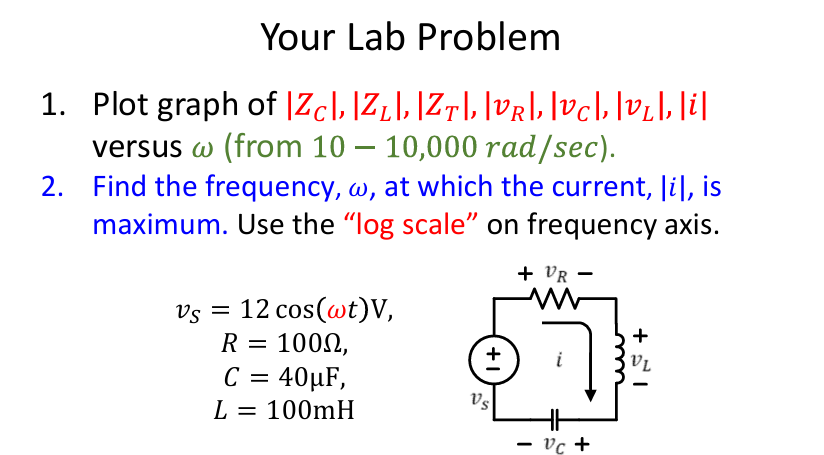

%clear variable ,clear graph
clear;clf;
%Configure variables w, Vs, R, C, L
w = linspace(10,1e4,9991); %run w(from 10 - 10000 rad/sec)
Vs = 12;
R = 100;
C = 40*(10.^-6);
L = 100*(10.^-3);
%find Z (Prasor domain)
ZR = R;
ZL = i.*w.*L;
ZC = 1./(i.*w.*C);
ZT = ZR + ZC + ZL;
%find I & VR, VL, VC with ohm law
I = Vs./ZT;
VR = I.*ZR;
VL =  I.*ZL;
VC = I.*ZC;
%next ===> Plot graph

**Plot graph |ZC|**

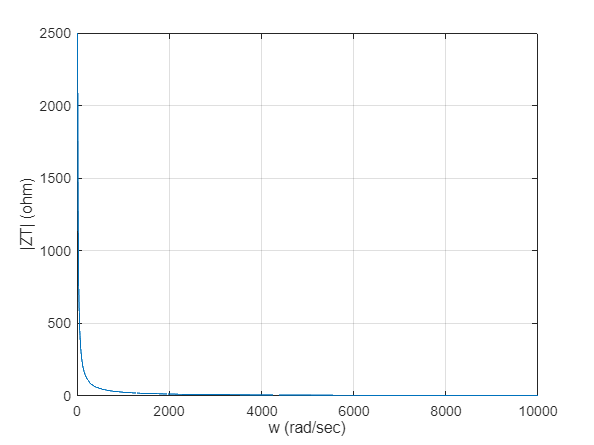

figure(1);
plot(w,abs(ZC));
grid on
xlabel("w (rad/sec)");
ylabel("|ZT| (ohm)");

**Plot graph |ZL|**

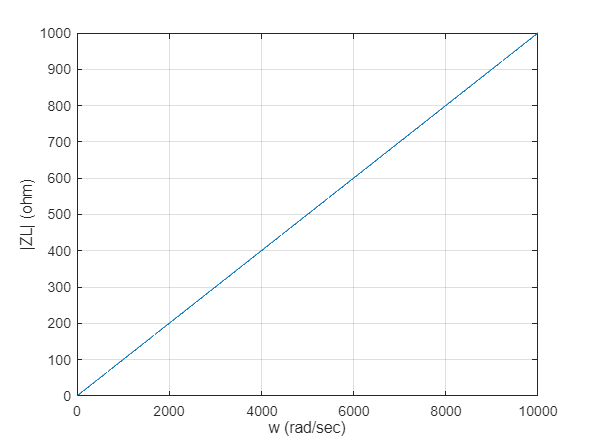

figure(2);
plot(w,abs(ZL));
grid on
xlabel("w (rad/sec)");
ylabel("|ZL| (ohm)");

**Plot graph |ZT|**

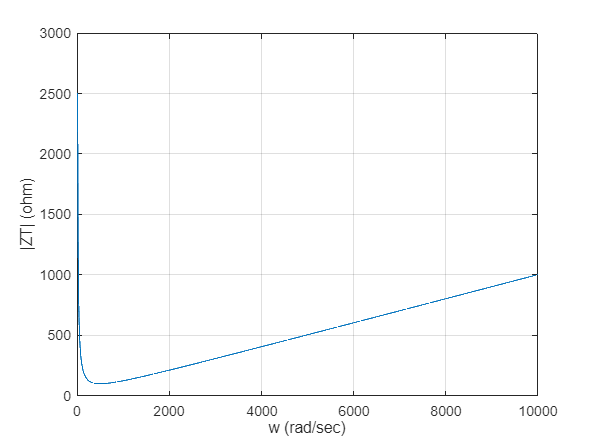

figure(3);
plot(w,abs(ZT));
grid on
xlabel("w (rad/sec)");
ylabel("|ZT| (ohm)");

**Plot graph |VR|**

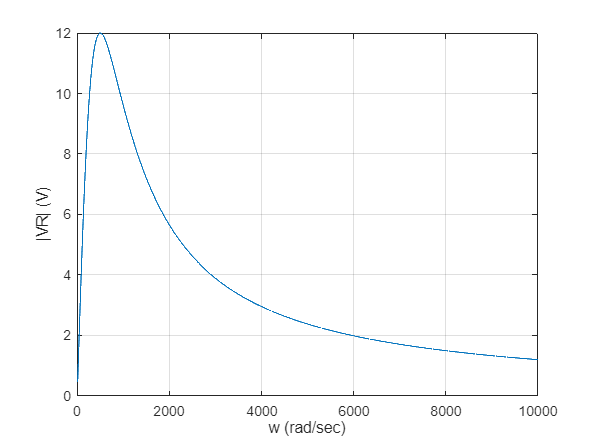

figure(4);
plot(w,abs(VR));
grid on
xlabel("w (rad/sec)");
ylabel("|VR| (V)");

**Plot graph |VC|**

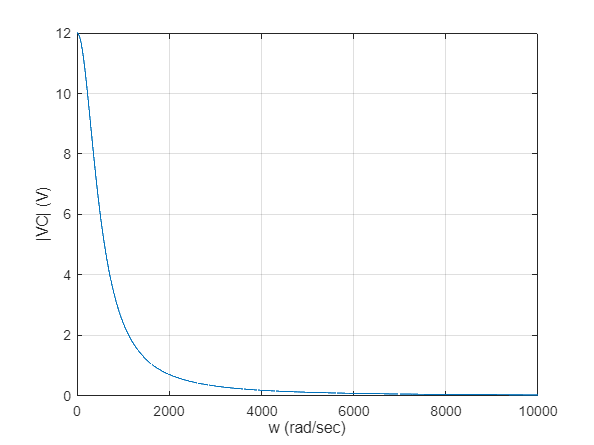

figure(5);
plot(w,abs(VC));
grid on
xlabel("w (rad/sec)");
ylabel("|VC| (V)");

**Plot graph |VL|**

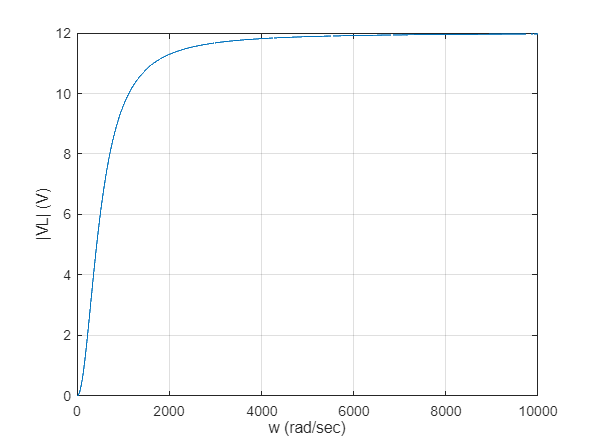

figure(6);
plot(w,abs(VL));
grid on
xlabel("w (rad/sec)");
ylabel("|VL| (V)");

**Plot graph |I|**

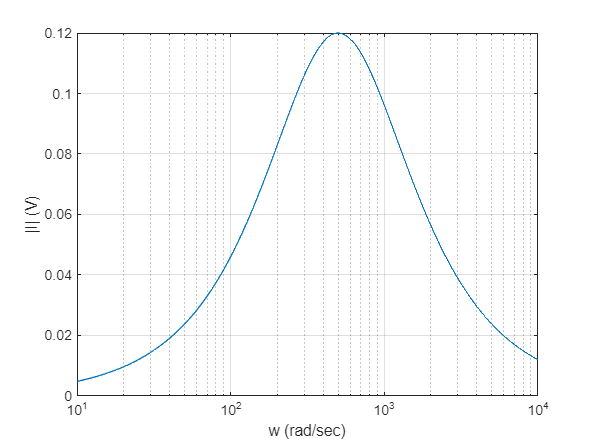

figure(7);
plot(w,abs(I));
grid on
xlabel("w (rad/sec)");
ylabel("|I| (V)");
xscale log %log scale of |I|

**Show result**

[Imax,Value] = max(I);
disp(['Maximum Current',num2str(abs(Imax)),"A"]); %Show result maximum current (A)

    "Maximum Current"    "0.12"    "A"



disp(['W at maximum Current',num2str(w(Value)),"rad/sec"]); %Show result W at maximum current (rad/sec)

    "W at maximum Current"    "500"    "rad/sec"

